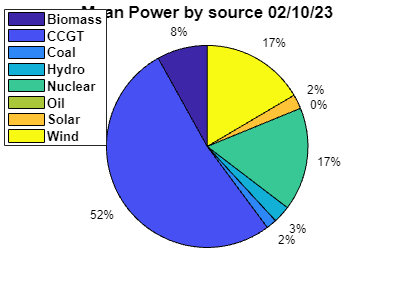

load("Q1stats.mat");

meanPower=[meanBiomass, meanCCGT, meanCoal, meanHydro, meanNuclear, meanOil, meanSolar, meanWind];
meanPowerLabels={'Biomass','CCGT', 'Coal', 'Hydro','Nuclear','Oil','Solar','Wind'};

pie(meanPower);
legend(meanPowerLabels)
title("Mean Power by source 02/10/23","FontSize",14);

legend("Position", [0.047619,0.58659,0.17949,0.31098],"FontSize",11,"FontWeight","bold")

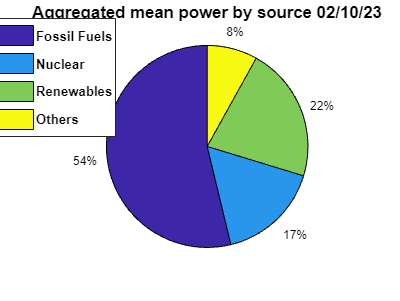


meanPowerAggs=[meanFossilAg, meanNuclearAg, meanRenewableAg, meanOthersAg];
meanPowerAggsLabels={'Fossil Fuels','Nuclear','Renewables', 'Others'};

pie(meanPowerAggs);
legend(meanPowerAggsLabels)
title("Aggregated mean power by source 02/10/23","FontSize",14);

legend("Position", [0.047619,0.58659,0.17949,0.31098],"FontSize",11,"FontWeight","bold")

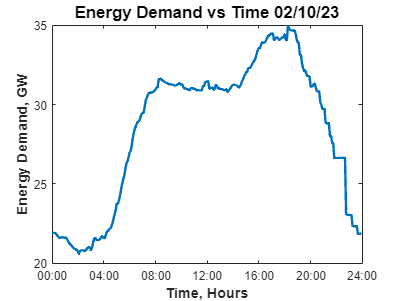



time = 0:287;
figure
plot(time,demand/1000, "LineWidth",2)
title("Energy Demand vs Time 02/10/23","FontSize",14)
xlabel("Time, Hours","FontSize",12,"FontWeight","bold")
ylabel("Energy Demand, GW","FontSize", 12,"FontWeight","bold")
xticks([0 48 96 144 192 240 288])
xticklabels({'00:00', '04:00', '08:00', '12:00', '16:00', '20:00', '24:00'})
xlim([0 288])


load("Q4stats.mat");

Q4Time = 0:2012;
figure
yyaxis right
plot(Q4Time,demandAugust/1000,"LineWidth",2)
title("Energy Demand vs Time 15-22/08/22","FontSize",14)
xlabel("Time, Days","FontSize",12,"FontWeight","bold")
ylabel("Energy Demand, GJ","FontSize", 12,"FontWeight","bold")
xticks([144 432 719 1007 1294 1581 1869])
xticklabels({'15/08', '16/08', '17/08', '18/08', '19/08', '20/08', '21/08'})


mean15Aug = mean(demandAugust(1:288));
mean16Aug = mean(demandAugust(289:576));
mean17Aug = mean(demandAugust(577:861));
mean18Aug = mean(demandAugust(862:1149));
mean19Aug = mean(demandAugust(1150:1437));
mean20Aug = mean(demandAugust(1438:1725));
mean21Aug = mean(demandAugust(1726:2013));

Aug15means = [mean15Aug, mean16Aug, mean17Aug, mean18Aug, mean19Aug, mean20Aug, mean21Aug];
augDays = 144:288:2013

augDays =          144         432         720        1008        1296        1584        1872


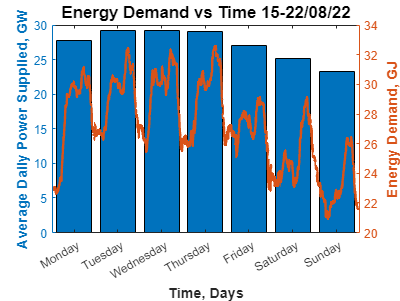

yyaxis left
bar(augDays, Aug15means/1000,"grouped")
ylabel("Average Daily Power Supplied, GW","FontSize", 12,"FontWeight","bold")
xticks([144 432 719 1007 1294 1581 1869])
xticklabels({'Monday', 'Tuesday', 'Wednesday', 'Thursday', 'Friday', 'Saturday', 'Sunday'})
xlim([0 2021])

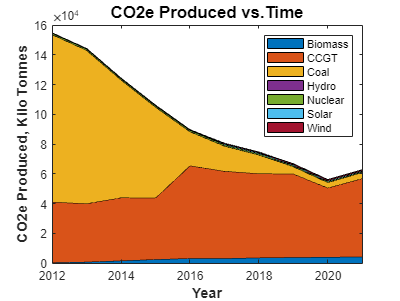


load("Q5stats.mat")

%Take the average amount of MW produced for that year to get MW
%multiply by the amount of hours in the year to get MWh
%Multiply by the CO2 coefficient to get tonnes of Co2 produced

Co2Biomass12 = mean(biomass1(1:105255))*8784*0.23;
Co2Biomass13 = mean(biomass1(105256:209983))*8760*0.23;
Co2Biomass14 = mean(biomass1(209984:314830))*8760*0.23;
Co2Biomass15 = mean(biomass1(314831:419705))*8760*0.23;
Co2Biomass16 = mean(biomass1(419706:524565))*8784*0.23;
Co2Biomass17 = mean(biomass1(524566:629596))*8760*0.23;
Co2Biomass18 = mean(biomass1(629597:734584))*8760*0.23;
Co2Biomass19 = mean(biomass1(734585:839500))*8760*0.23;
Co2Biomass20 = mean(biomass1(839501:944908))*8784*0.23;
Co2Biomass21 = mean(biomass1(944909:1050010))*8760*0.23;
Co2Biomass = [Co2Biomass12, Co2Biomass13, Co2Biomass14, Co2Biomass15, Co2Biomass16, Co2Biomass17, Co2Biomass18, Co2Biomass19, Co2Biomass20, Co2Biomass21];

Co2CCGT12 = mean(ccgt1(1:105255))*8784*0.49;
Co2CCGT13 = mean(ccgt1(105256:209983))*8760*0.49;
Co2CCGT14 = mean(ccgt1(209984:314830))*8760*0.49;
Co2CCGT15 = mean(ccgt1(314831:419705))*8760*0.49;
Co2CCGT16 = mean(ccgt1(419706:524565))*8784*0.49;
Co2CCGT17 = mean(ccgt1(524566:629596))*8760*0.49;
Co2CCGT18 = mean(ccgt1(629597:734584))*8760*0.49;
Co2CCGT19 = mean(ccgt1(734585:839500))*8760*0.49;
Co2CCGT20 = mean(ccgt1(839501:944908))*8784*0.49;
Co2CCGT21 = mean(ccgt1(944909:1050010))*8760*0.49;
Co2CCGT = [Co2CCGT12, Co2CCGT13, Co2CCGT14, Co2CCGT15, Co2CCGT16, Co2CCGT17, Co2CCGT18, Co2CCGT19, Co2CCGT20, Co2CCGT21];

Co2Coal12 = mean(coal1(1:105255))*8784*0.82;
Co2Coal13 = mean(coal1(105256:209983))*8760*0.82;
Co2Coal14 = mean(coal1(209984:314830))*8760*0.82;
Co2Coal15 = mean(coal1(314831:419705))*8760*0.82;
Co2Coal16 = mean(coal1(419706:524565))*8784*0.82;
Co2Coal17 = mean(coal1(524566:629596))*8760*0.82;
Co2Coal18 = mean(coal1(629597:734584))*8760*0.82;
Co2Coal19 = mean(coal1(734585:839500))*8760*0.82;
Co2Coal20 = mean(coal1(839501:944908))*8784*0.82;
Co2Coal21 = mean(coal1(944909:1050010))*8760*0.82;
Co2Coal = [Co2Coal12, Co2Coal13, Co2Coal14, Co2Coal15, Co2Coal16, Co2Coal17, Co2Coal18, Co2Coal19, Co2Coal20, Co2Coal21];

Co2Hydro12 = mean(hydro1(1:105255))*8784*0.024;
Co2Hydro13 = mean(hydro1(105256:209983))*8760*0.024;
Co2Hydro14 = mean(hydro1(209984:314830))*8760*0.024;
Co2Hydro15 = mean(hydro1(314831:419705))*8760*0.024;
Co2Hydro16 = mean(hydro1(419706:524565))*8784*0.024;
Co2Hydro17 = mean(hydro1(524566:629596))*8760*0.024;
Co2Hydro18 = mean(hydro1(629597:734584))*8760*0.024;
Co2Hydro19 = mean(hydro1(734585:839500))*8760*0.024;
Co2Hydro20 = mean(hydro1(839501:944908))*8784*0.024;
Co2Hydro21 = mean(hydro1(944909:1050010))*8760*0.024;
Co2Hydro = [Co2Hydro12, Co2Hydro13, Co2Hydro14, Co2Hydro15, Co2Hydro16, Co2Hydro17, Co2Hydro18, Co2Hydro19, Co2Hydro20, Co2Hydro21];

Co2Nuclear12 = mean(nuclear1(1:105255))*8784*0.012;
Co2Nuclear13 = mean(nuclear1(105256:209983))*8760*0.012;
Co2Nuclear14 = mean(nuclear1(209984:314830))*8760*0.012;
Co2Nuclear15 = mean(nuclear1(314831:419705))*8760*0.012;
Co2Nuclear16 = mean(nuclear1(419706:524565))*8784*0.012;
Co2Nuclear17 = mean(nuclear1(524566:629596))*8760*0.012;
Co2Nuclear18 = mean(nuclear1(629597:734584))*8760*0.012;
Co2Nuclear19 = mean(nuclear1(734585:839500))*8760*0.012;
Co2Nuclear20 = mean(nuclear1(839501:944908))*8784*0.012;
Co2Nuclear21 = mean(nuclear1(944909:1050010))*8760*0.012;
Co2Nuclear = [Co2Nuclear12, Co2Nuclear13, Co2Nuclear14, Co2Nuclear15, Co2Nuclear16, Co2Nuclear17, Co2Nuclear18, Co2Nuclear19, Co2Nuclear20, Co2Nuclear21];

Co2Solar12 = mean(solar1(1:105255))*8784*0.048;
Co2Solar13 = mean(solar1(105256:209983))*8760*0.048;
Co2Solar14 = mean(solar1(209984:314830))*8760*0.048;
Co2Solar15 = mean(solar1(314831:419705))*8760*0.048;
Co2Solar16 = mean(solar1(419706:524565))*8784*0.048;
Co2Solar17 = mean(solar1(524566:629596))*8760*0.048;
Co2Solar18 = mean(solar1(629597:734584))*8760*0.048;
Co2Solar19 = mean(solar1(734585:839500))*8760*0.048;
Co2Solar20 = mean(solar1(839501:944908))*8784*0.048;
Co2Solar21 = mean(solar1(944909:1050010))*8760*0.048;
Co2Solar = [Co2Solar12, Co2Solar13, Co2Solar14, Co2Solar15, Co2Solar16, Co2Solar17, Co2Solar18, Co2Solar19, Co2Solar20, Co2Solar21];

Co2Wind12 = mean(wind1(1:105255))*8784*0.012;
Co2Wind13 = mean(wind1(105256:209983))*8760*0.012;
Co2Wind14 = mean(wind1(209984:314830))*8760*0.012;
Co2Wind15 = mean(wind1(314831:419705))*8760*0.012;
Co2Wind16 = mean(wind1(419706:524565))*8784*0.012;
Co2Wind17 = mean(wind1(524566:629596))*8760*0.012;
Co2Wind18 = mean(wind1(629597:734584))*8760*0.012;
Co2Wind19 = mean(wind1(734585:839500))*8760*0.012;
Co2Wind20 = mean(wind1(839501:944908))*8784*0.012;
Co2Wind21 = mean(wind1(944909:1050010))*8760*0.012;
Co2Wind = [Co2Wind12, Co2Wind13, Co2Wind14, Co2Wind15, Co2Wind16, Co2Wind17, Co2Wind18, Co2Wind19, Co2Wind20, Co2Wind21];

figure
Years = [2012 2013 2014 2015 2016 2017 2018 2019 2020 2021];
Co2Total = ([Co2Biomass; Co2CCGT; Co2Coal; Co2Hydro; Co2Nuclear; Co2Solar; Co2Wind]')/1000;


area(Years, Co2Total)
title("CO2e Produced vs.Time","FontSize",14)
xlabel("Year","FontSize",12,"FontWeight","bold")
ylabel("CO2e Produced, Kilo Tonnes","FontSize", 12,"FontWeight","bold")
xlim([2012 2021])
legend({'Biomass', 'CCGT', 'Coal', 'Hydro', 'Nuclear', 'Solar', 'Wind'})